# Simple Image Enhancements

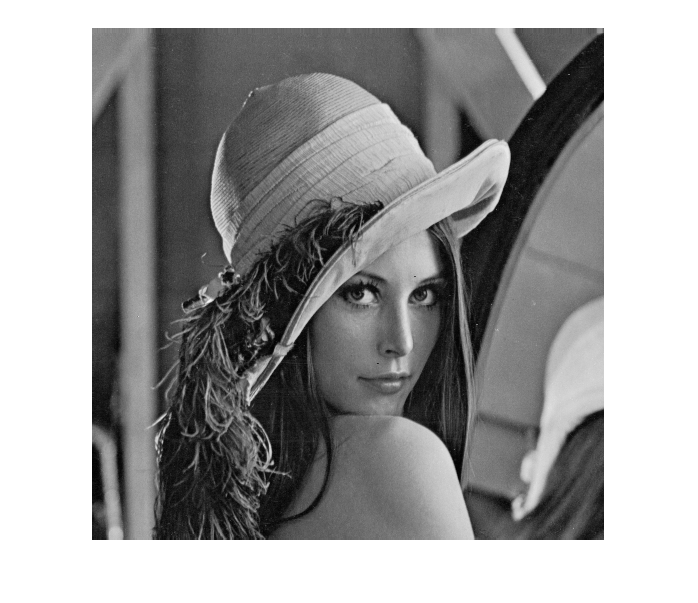

f = imread('lena.jpg'); 
imshow(f)

## Intensity transformation functions

Create negative of an image

max_val = max(f(:))

max_val = uint8
249

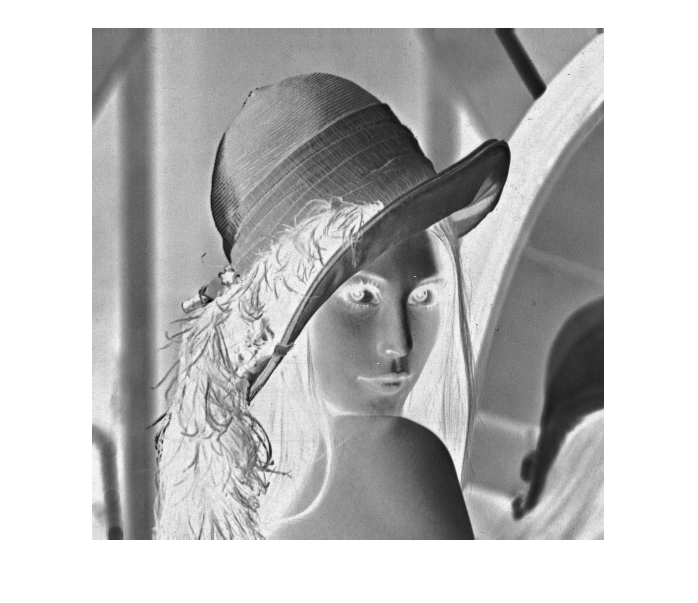

imshow(max_val - f)

Using MATLAB function to create the same effect

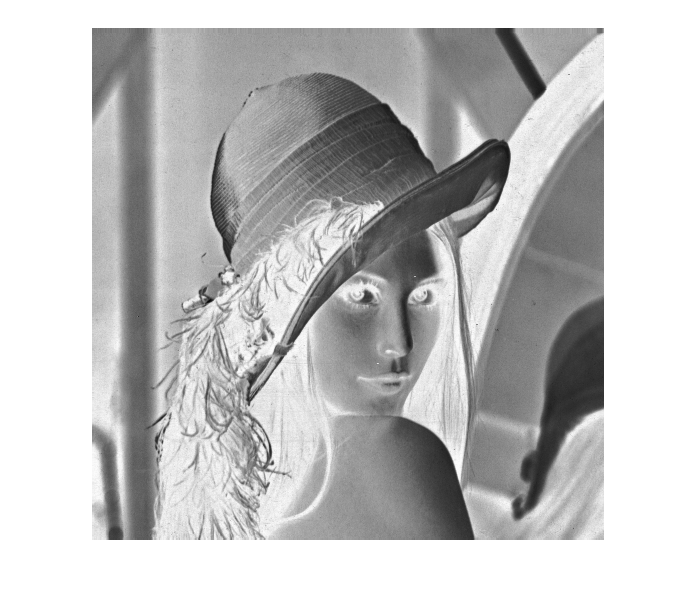

imshow(imadjust(f, [0 1], [1 0])) % or incomplement(f)

Contrast stretching expands a narrow of input levels to a wide range (stretched) range of output levels. The result is an image with higher contrast:

low_high = stretchlim(f)

low_high =     0.0431
    0.8235


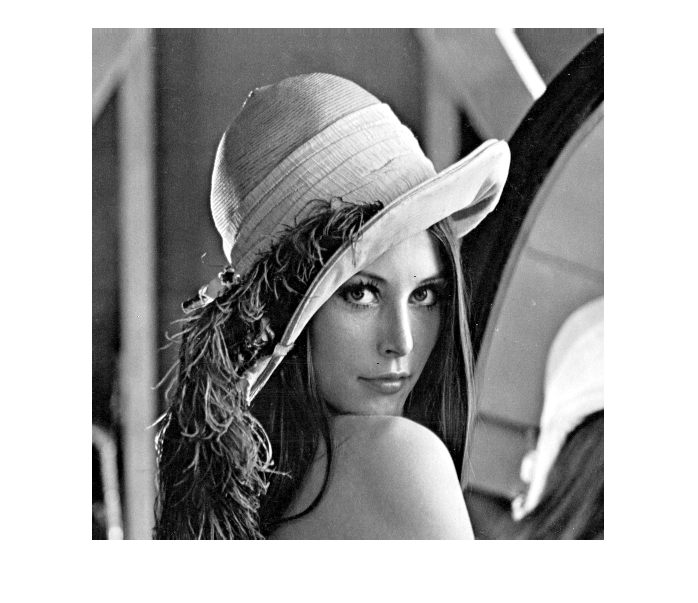

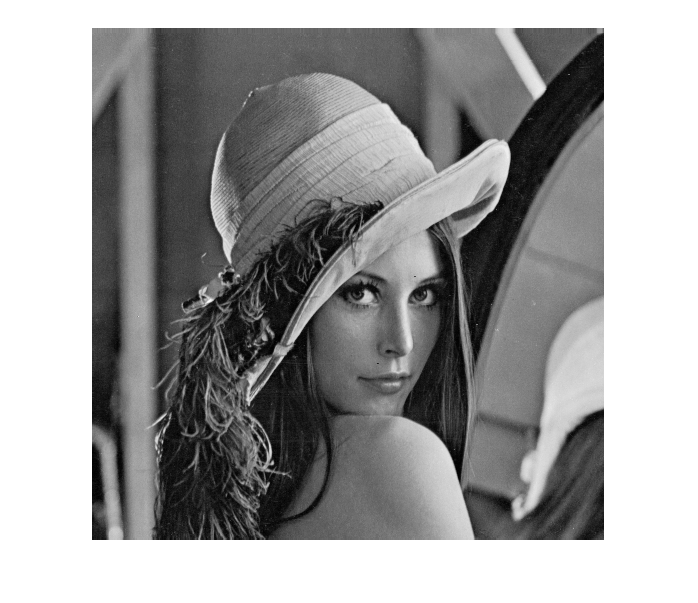

imshow(imadjust(f, low_high, [ ]))

## Image Histograms

The histogram of an image shows  the number of pixels (y-axis) for each possible intensity value (x-axis)

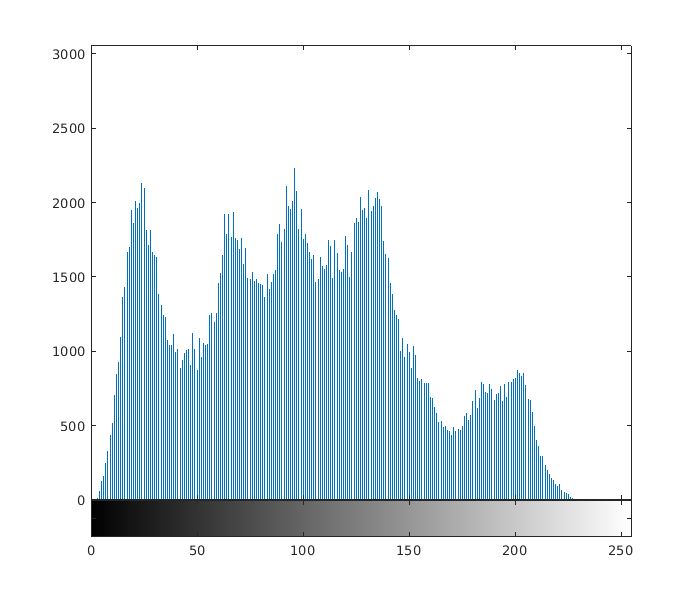

imhist(f)

Normalised histogram as plot:

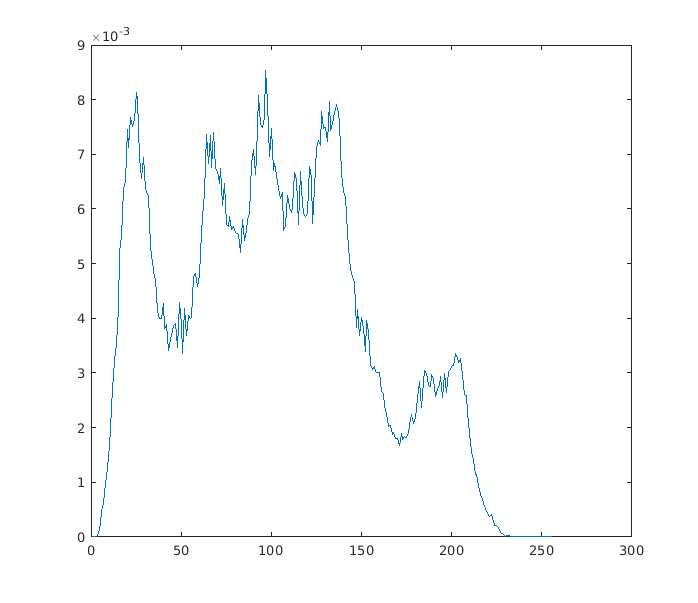

plot(imhist(f) ./ numel(f))

Bar graph:

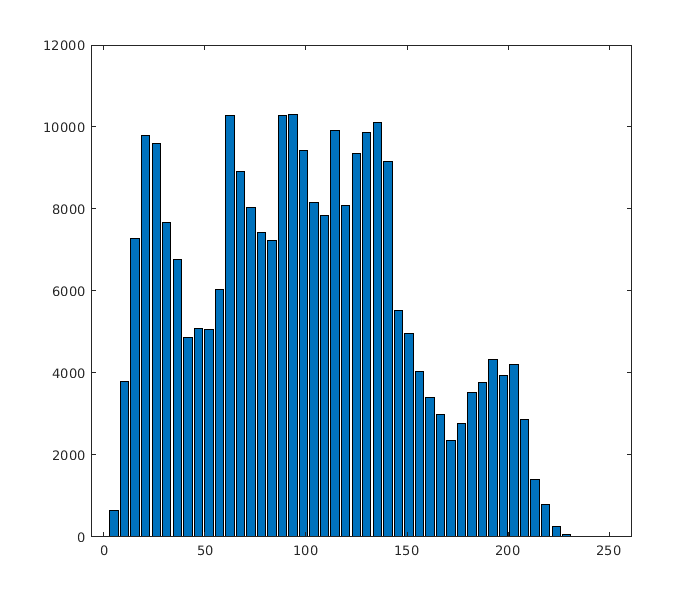

bins = 50;
h = imhist(f, bins);
horz = linspace(0, 255, bins);
bar(horz, h)

## Linear filtering

The concept of linear filtering has its roots in the use of the Fourier transform for signal processing in the frequency domain.

In signal processing, cross-correlation is a measure of similarity of two waveforms as a function of a time-lag applied to one of them. This is also known as a sliding dot product of the two signals.